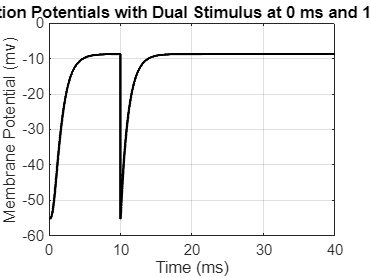

%filename: in_HH.m
%Units:
%voltage is in millivolts (mV)
%current is in microamperes (muA)
%length is in centimeters (cm)
%time is in milliseconds (ms)
%note that microfarads =
%microamperes*milliseconds/millivolt
%= muA*ms/mV
%
%initialize membrane parameters:
%membrane capacitance per unit area:
C=1.0 ;     %(muF/cm^2)
%max possible Na+ conductance per unit area:
gNabar=120 ;%((muA/mV)/cm^2)
%max possible K+ conductance per unit area:
gKbar=36 ;  %((muA/mV)/cm^2)
%leakage conductance per unit area:
gLbar=0.3 ; %((muA/mV)/cm^2)
%Na+ equilibrium potential:
ENa = 45;   %(mV)
%K+ equilibrium potential:
EK = -82;  %(mV) Normal -82
%leakage channel reversal potential:
EL = -59 ;  %(mV)
%
%initialize time step and experiment duration:
dt=0.01  ;   %time step duration (ms)
tmax=40 ;%duration of experiment (ms)
t=0:dt:tmax;
nt=length(t);
%total number of time steps in the experiment:
klokmax=ceil(tmax/dt);
%
%initialize arrays that hold data for plotting:
mhn_plot=zeros(3,klokmax);
v_plot=zeros(1,klokmax);
t_plot=zeros(1,klokmax);
%
%initialize parameters that define the experiment:
%the neuron is at rest (v= -70 mV) prior to t=0;
%at t=0 a current shock is applied after which v= -55 mV;
%then a subsequent 15 muA current pulse of 1 ms duration
%is applied beginning at t=10 ms.
%voltage prior to t=0:
vhold=  -70;  %(mV) (original -70)
%voltage just after t=0:
vstart= vhold+15;  %(mV)
%(change in v is result of current shock applied at t=0)
%
%initialize parameters of subsequent current pulse:
t1p=0 ;     %starting time (ms)
t2p=t1p+10  ;     %stopping time (ms)
ip=0 ;      %current applied (muA)
%
%initialize checking parameter
check=1 ;    %set check=1 to enable self-checking
 %set check=0 to disable self-checking
m=zeros(1,nt);
h=zeros(1,nt);
n=zeros(1,nt);
V=vhold*ones(1,nt);
V(1)=vhold;
m(1)=alpham(V(1))/(alpham(V(1))+ betam(V(1)));
h(1)=alpham(V(1))/(alpham(V(1))+ betam(V(1)));
n(1)=alpham(V(1))/(alpham(V(1))+ betam(V(1)));
for i=1:nt-1
    if abs(t(i)-t1p)<dt
        V(i)=vstart;
    elseif abs(t(i)-t2p)<dt
        V(i)=vstart;
    end

    am=alpham(V(1));bm=betam(V(1));
    ah=alpham(V(1));bh=betam(V(1));
    an=alpham(V(1));bn=betam(V(1));

    m(i+1)=m(i)+dt*(am*(1-m(i))-bm*m(i));
    h(i+1)=h(i)+dt*(ah*(1-h(i))-bh*h(i));
    n(i+1)=n(i)+dt*(an*(1-n(i))-bn*n(i));
    gNa=120*m(i)^3*h(i);
    gk=36*n(i)^4;
    gL=0.3;

    ENa=45;
    Ek=-82;
    EL=-59;

    INa=gNa*(V(i)-ENa);
    IK=gk*(V(i)-EK);
    IL=gL*(V(i)-EL);

    V(i+1)= V(i)-dt * (INa + IK + IL);
end
figure;
plot(t,V,'k','LineWidth',1.5);hold on;
xlabel('Time (ms)');
ylabel('Membrane Potential (mv)');
title('Action Potentials with Dual Stimulus at 0 ms and 10 ms')
grid on;